%input signal
signal_bits = randi([0 1],10000,1);
symbols = randi([0 3],10000,1);

grouped_bits = reshape(signal_bits.', [], 2);
%Gray Coding
qpsk_keys = {'00','01','11','10'};
qpsk_values = ["00","01","10","11"];
const_map = containers.Map(qpsk_keys,qpsk_values);

## QPSK using the communications toolbox

To Do

> create different amounts of noise

> SNR vs BER (as noise increases there will be a limiing error rate)

(Later mutual information)

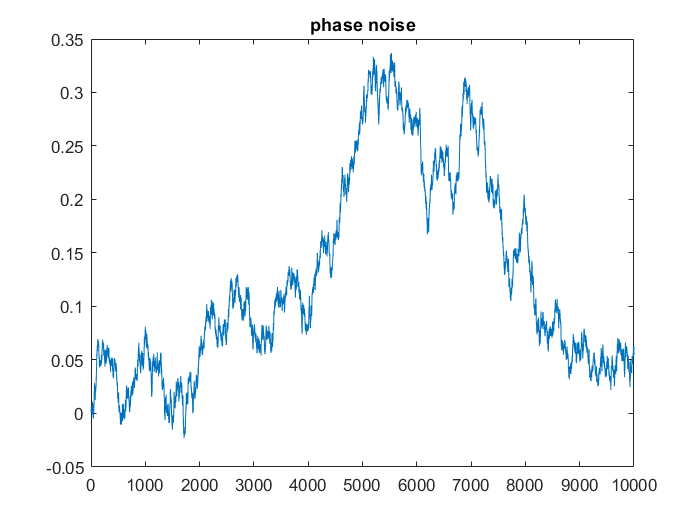

%Predifined functions as provided by the communications toolbox

mod_bits=pskmod(symbols,4,0,"gray");
symbol_rate = 100e9;
time_step = 1/symbol_rate;
linewidth = 100e3; %kHz
var=2*pi*linewidth*time_step;
%phase_noise=exp(1i*2*pi*rand(10000,1));
phase_noise=cumsum(sqrt(var)*randn(10000,1));
plot(phase_noise)
title('phase noise')


noisy_mod_bits = mod_bits .* phase_noise;

demod_bits=pskdemod(mod_bits,4);

noisy_demod_bits = pskdemod(noisy_mod_bits,4);

if (demod_bits ~= symbols)
     disp("huh")
end

## Plotting QPSK output, after noise has been added

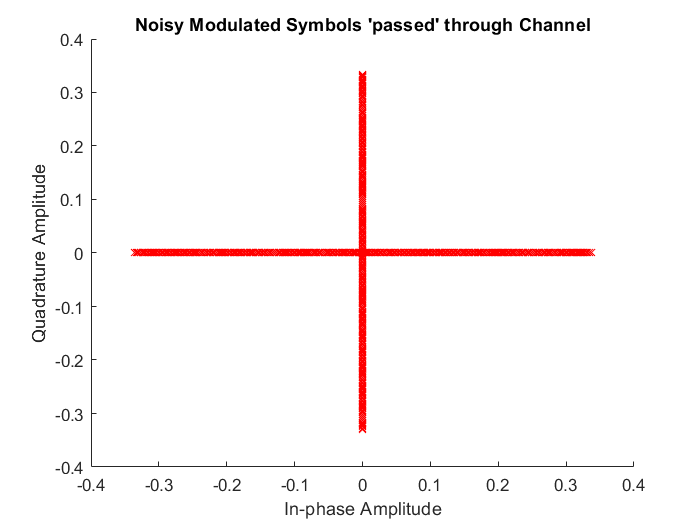


Re=real(noisy_mod_bits);
Im=imag(noisy_mod_bits);

figure
scatter(real(noisy_mod_bits),imag(noisy_mod_bits),'rx')
title("Noisy Modulated Symbols 'passed' through Channel")
xlabel("In-phase Amplitude")
ylabel("Quadrature Amplitude")

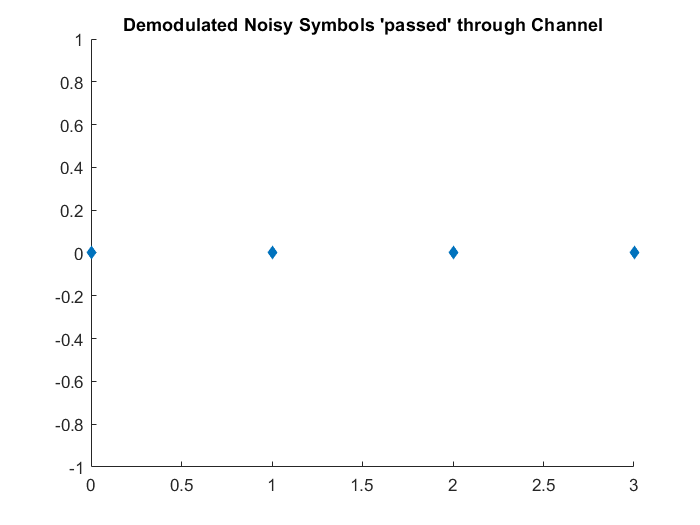


figure
scatter(real(noisy_demod_bits),imag(noisy_demod_bits),"filled","d")
title("Demodulated Noisy Symbols 'passed' through Channel")

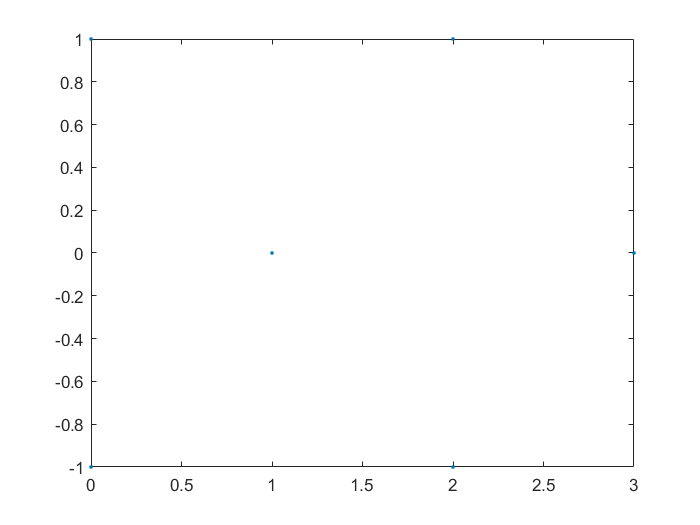

%Check dec2bin function
figure
plot(noisy_demod_bits,mod_bits,'.')

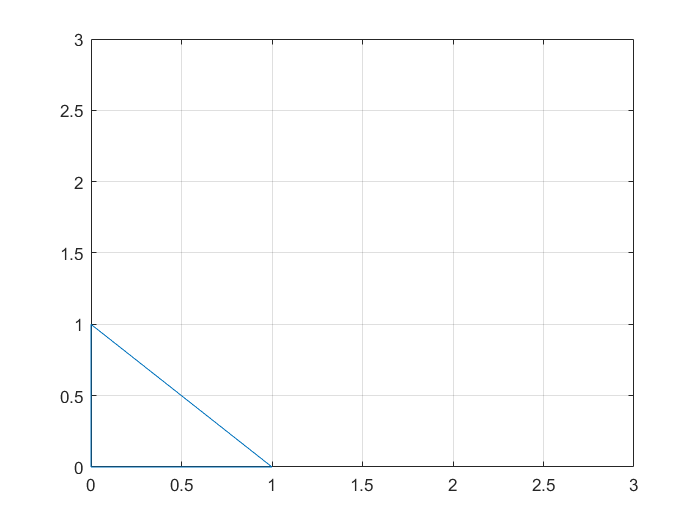

plot(mod_bits)
axis([0,3,0,3])
grid on

## Personal QPSK function testing and plotting for comparision

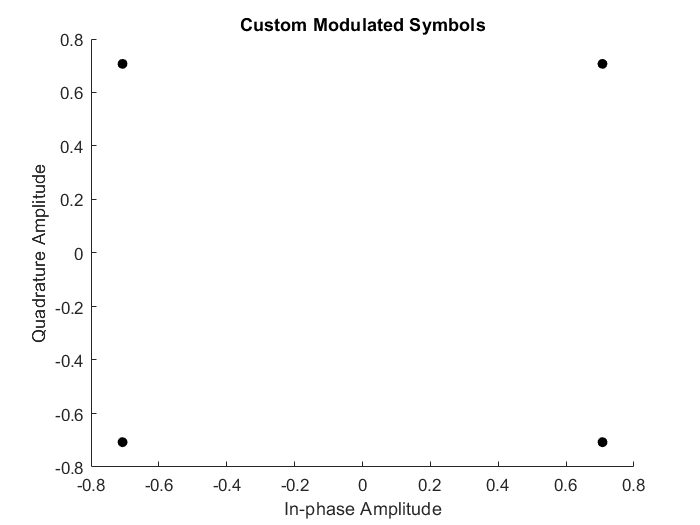

%Attempt at implementation of phase-shift-keying:
custom_moded_bits = zeros(size(grouped_bits,1),1);

%Modulation
for i = 1:size(grouped_bits,1)
    custom_moded_bits(i) = pskmodulation(grouped_bits(i,:));
end
figure
scatter(real(custom_moded_bits'),imag(custom_moded_bits'),'black',"filled")
title("Custom Modulated Symbols")
xlabel("In-phase Amplitude")
ylabel("Quadrature Amplitude")


%Demodulation
custom_demoded_bits =(zeros(size(grouped_bits)));
for i = 1:size(grouped_bits,1)
    custom_demoded_bits(i,:) = pskdemodulation(custom_moded_bits(i));
end

if (custom_demoded_bits ~= grouped_bits)
     disp("huh")
end

## Functions for modulation and demodulation

Created as a proof-of-concept. They would require generalisation and optimisation depending on the requirements.

function psk_moded_symbols = pskmodulation(grouped_bits)

%maps incoming bits in a 1x2 matrix into gray-mapped complex symbols 

 if (grouped_bits(1,1) == 0) && (grouped_bits(1,2) == 0) 
        psk_moded_symbols = exp(1i*pi/4);
 elseif (grouped_bits(1,1) == 0) && (grouped_bits(1,2) == 1)
        psk_moded_symbols = exp(1i*3*pi/4);
 elseif (grouped_bits(1,1) == 1) && (grouped_bits(1,2) == 0)
        psk_moded_symbols = exp(1i*(-1)*pi/4);
 elseif (grouped_bits(1,1) == 1) && (grouped_bits(1,2) == 1)
        psk_moded_symbols = exp(1i*(-3)*pi/4);
 else
     disp("error")
     psk_moded_symbols = nan;
 end

end

%Finds the minimum distance of an incoming complex symbol and all known
%symbols. Then uses the closest symbol for demodulation

function psk_demoded_bits = pskdemodulation(symbol)
    
  qpsk_symbols = [(1+1j)/sqrt(2) (-1+1j)/sqrt(2) (-1-1j)/sqrt(2) (1-1j)/sqrt(2)];
  demod_qpsk_symbols = [0 0; 0 1; 1 0; 1 1];
  min_dist = [0 100];
  distances = zeros(1,4);
  for i = 1:4
    distances(1,i) = abs(symbol - qpsk_symbols(1,i));
    if distances(i) < min_dist(1,2)
        min_dist = [i distances(i)];
    end
  end
  psk_demoded_bits = demod_qpsk_symbols(min_dist(1,1),:);
end